# Traccia 2: Manipolatore a 2 DoF

### Manipolatore a 2 DoF planare con attuatori elastici in serie (SEA)

clear; clc; close all;

config
model = Model(init);

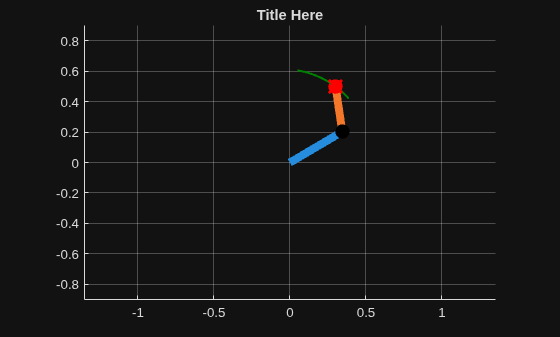

target = [0.3;0.5];
model.targetQ(target)

*Figura 1: Manipolatore planare *$2R$* con Series Elastic Actuators (SEA). I dischi ai giunti rappresentano i motori *$(M_1 , M_2)$* con coordinate [*$\theta_1$*, *$\theta_2$]*. Le molle angolari di rigidezza [*$k_1$*, *$k_2$]* collegano elasticamente in serie i rotori dei motori ai link corrispondenti, con coordinate articolari [*$q_1$*, *$q_2$]* .*

### Problem Statement

Si consideri un manipolatore planare a due gradi di libertà ($2R$) con attuatori elastici in serie (Series Elastic Actuators, SEA), come illustrato in figura 1. Il sistema è composto da due link rigidi di lunghezza $l_1$ e $l_2$ e massa concentrata $m_1$, $m_2$ all’estremità, collegati in serie tramite giunti rotazionali. A ciascun giunto è interposta una molla angolare di rigidezza $k_i$ che accoppia in serie il rotore del motore $i$-esimo, la cui posizione angolare è $\theta_i$ , con il link corrispondente, la cui posizione angolare è $q_i$. La deformazione elastica al giunto $i$ è $\delta_i$ = $\theta_i$ − $q_i$ .

### Parametri

%% ========================================================================
%% 1. PARAMETRI NOMINALI (Dalla Tabella 1)
%% ========================================================================
m1_nom = 1.0;      % kg
m2_nom = 0.8;      % kg
l1     = 0.4;      % m
l2     = 0.3;      % m
g      = 9.81;     % m/s^2

% Motori e Molle (SEA)
Jm1 = 0.01; Jm2 = 0.01;   % kg m^2
Bm1 = 0.02; Bm2 = 0.02;   % N m s/rad
k1  = 50;   k2  = 40;     % N m/rad

% Parametri scelti arbitrariamente (Esempio di valori sensati per XX, YY, ZZ)
wn_nom   = 30;     % rad/s (Frequenza naturale attuatore)
zeta_nom = 0.7;    % Smorzamento nominale attuatore
tau_d    = 0.005;  % secondi (Ritardo di trasporto - 5 ms)

%% ========================================================================
%% 2. DEFINIZIONE DELLE INCERTEZZE (Per mu-analysis e Robust Control)
%% ========================================================================
% Ipotizziamo un'incertezza del valore scelto (es. +-10% sulle masse e molle)
p_inc = 10; % Percentuale di incertezza

m1 = ureal('m1', m1_nom, 'Percentage', p_inc);
m2 = ureal('m2', m2_nom, 'Percentage', p_inc);
k1_inc = ureal('k1', k1, 'Percentage', p_inc);
k2_inc = ureal('k2', k2, 'Percentage', p_inc);

Ks = diag([k1_inc, k2_inc]);
Jm = diag([Jm1, Jm2]);
Bm = diag([Bm1, Bm2]);

%% ========================================================================
%% 3. PUNTO DI EQUILIBRIO E LINEARIZZAZIONE
%% ========================================================================
% Scegliamo una configurazione di equilibrio (es. q1 = 0, q2 = pi/4)
q1_bar = 0;
q2_bar = pi/4;

% Calcolo della Matrice di Inerzia M(q) valutata all'equilibrio
m11 = (m1 + m2)*l1^2 + m2*l2^2 + 2*m2*l1*l2*cos(q2_bar);
m12 = m2*l2^2 + m2*l1*l2*cos(q2_bar);
m21 = m12;
m22 = m2*l2^2;
M_bar = [m11, m12; m21, m22];

% Jacobiano del Vettore Gravitazionale dG/dq valutato all'equilibrio
dG_dq11 = -(m1 + m2)*g*l1*sin(q1_bar) - m2*g*l2*sin(q1_bar + q2_bar);
dG_dq12 = -m2*g*l2*sin(q1_bar + q2_bar);
dG_dq21 = -m2*g*l2*sin(q1_bar + q2_bar);
dG_dq22 = -m2*g*l2*sin(q1_bar + q2_bar);
dG_dq = [dG_dq11, dG_dq12; dG_dq21, dG_dq22];

% Costruzione della matrice di Stato A (8x8) e della matrice Ingressi B (8x2)
% Stato ordinato come: x = [q1; q2; theta1; theta2; dq1; dq2; dtheta1; dtheta2]
A = [ zeros(2,2),   zeros(2,2),      eye(2,2),     zeros(2,2);
      zeros(2,2),   zeros(2,2),      zeros(2,2),   eye(2,2);
     -M_bar\(dG_dq + Ks),  M_bar\Ks,  zeros(2,2),   zeros(2,2);
      Jm\Ks,        -Jm\Ks,          zeros(2,2),  -Jm\Bm ];

B = [ zeros(2,2);
      zeros(2,2);
      zeros(2,2);
      Jm\eye(2,2) ];

% Matrice di uscita C: misuriamo le posizioni dei link (q1, q2)
C = [eye(2,2), zeros(2,6)];
D = zeros(2,2);

% Creazione del sistema incerto USS (Uncertain State Space)
sys_robot = ss(A, B, C, D);

%% ========================================================================
%% 4. MODELLO DEGLI ATTUATORI CON RITARDO DI PADÉ
%% ========================================================================
% Funzione di trasferimento nominale del secondo ordine per i motori
s = tf('s');
G_motor_nominal = wn_nom^2 / (s^2 + 2*zeta_nom*wn_nom*s + wn_nom^2);

% Approssimazione di Padé del 1° ordine per il ritardo di trasporto e^(-tau_d*s)
[num_pade, den_pade] = pade(tau_d, 1);
G_delay = tf(num_pade, den_pade);

% Funzione di trasferimento totale dell'attuatore (Filtro + Ritardo)
G_attuatore = G_motor_nominal * G_delay * eye(2); 

% Connessione in cascata: l'attuatore pilota gli ingressi del robot
sys_total_incerto = sys_robot * G_attuatore;

%% ========================================================================
%% 5. STRUTTURA PER IL PROGETTO DEI CONTROLLORI (Esempio cenni H-inf / mu)
%% ========================================================================
disp('Modello del sistema incerto creato con successo!');

Modello del sistema incerto creato con successo!


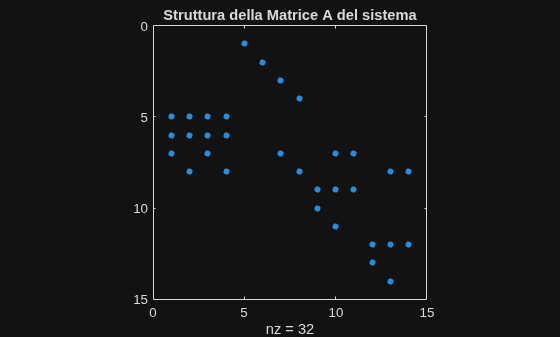

spy(sys_total_incerto.NominalValue.A); title('Struttura della Matrice A del sistema');

### Dinamica del Sistema

Le equazioni del moto si suddividono in due sottosistemi accoppiati tramite la coppia elastica dei SEA. La dinamica dei link è:


$$M (q) \ddot{q} + C(q, \dot{q}) \dot{q} + G(q) = Ks (\theta - q)$$


mentre la dinamica dei motori è:


$$J_m \ddot{\theta} + B_m \dot{\theta} = \tau - K_s (\theta - q)$$


dove 

- $\tau = [\tau_1, \tau_2 ]^\top$ è il vettore delle coppie ai motori (ingressi di controllo)

- $K_s = diag[k_1 , k_2]$ è la matrice di rigidezza

- $J_m = diag[Jm_1 , Jm_2]$ inerzia

- $B_m = diag[Bm_1 , Bm_2]$ smorzamento dei motori.